# Example 1: Double Integrator

Clear the work environment and check dependencies.

clear; clc; close all;
% Check if user has Yalmip installed
has_yalmip = exist("yalmip",'file');
if(has_yalmip)
    yalmip('clear')
end
% Check for MPT3
assert(exist("Polyhedron","file"), ...
    "MPT3 toolbox is required.")

## Problem Description

### Enter Problem Data

Enter the problem data as a structure. Begin with the system description:

$\mathbf{x}^+ = A\mathbf{x} + B\mathbf{u} + E\mathbf{d}$,

$\mathcal{D} = \{\mathbf{d} \in \mathbb{R}^q \mid \|\mathbf{d}\|_{\infty} \leq d_{\infty}\}$.

***Note****: Other set descriptions for *$\mathcal{D}$ *are allowed as long as it is compact, but require further  source code changes.*

dt = 0.1;
data.A = [1 dt; 0 1];
data.B = [0 dt]';
data.E = [0; dt];
data.d_max = 0.4; % Noise bound
data.n = size(data.A,1);
data.m = size(data.B,2);
% Check stabilizability
if(rank(ctrb(data.A, data.B)) ~= data.n)
  warning("Pair (A,B) is not controllable, " + ...
      "please verify it is stabilizable.")
end

Enter now state and input constraints

$\mathcal{X} = \{\mathbf{x} \in \mathbb{R}^n \mid  W\mathbf{x} \leq \mathbf{z}\}$,

$\mathcal{U} = \{\mathbf{u} \in \mathbb{R}^m \mid  M\mathbf{u} \leq \mathbf{b}\}$.

data.W = [1 0; -1 0];
data.z = [1; 1];
data.X = Polyhedron(data.W, data.z);
data.M = [1; -1];
data.b = [1.5; 1.5];
data.U = Polyhedron(data.M, data.b);

Check if $\mathcal{X}$ is compact and define the system outputs $\mathbf{y}$ and output constraint set $\mathcal{Y}$.

$\mathbf{y} = C_c \mathbf{x} + D_c \mathbf{u}$,

$\mathcal{Y} = \{\mathbf{y} \in \mathbb{R}^p \mid L\mathbf{y} \leq \mathbf{a}\}$.

if(isinf(data.X.volume)) % not compact data.X (manual entry)
  data.C_c = [1, 0; 0, 0];
  data.D_c = [0; 1];
  data.L = [eye(2); -eye(2)];
  data.a = [1; 1.5; 1; 1.5];
else % compact data.X
  data.C_c = [eye(data.n); zeros(data.m, data.n)];
  data.D_c = [zeros(data.n, data.m); eye(data.m)];
  data.L = [data.W; data.M];
  data.a = [data.z; data.b];
end
data.Y = Polyhedron(data.L, data.a);
assert(~isinf(data.Y.volume), "data.Y must be compact.");

Design the tracking output that will track the desired reference $\mathbf{r} \in \mathbb{R}^m$

$\mathbf{y}_r = C_r \mathbf{x} + D_r \mathbf{u}$.

data.C_r = [1, 0];
data.D_r = 0;
assert(size(data.C_r,1) == data.m)
assert(size(data.C_r,2) == data.n)
assert(size(data.D_r,1) == data.m)
assert(size(data.D_r,2) == data.m)

Obtain the steady-state manifold basis $G_x$ and $G_u$.

[data.G_x, data.G_u] = moas_ss_basis(data.A, data.B, data.C_r, data.D_r);

### Controller Design

Let us design the prestabilizing $\pi$ and nominal $\kappa$ controllers.

data.Q = diag([10, 1]);
data.R = 1e-4;
data.K_kappa = dlqr(data.A,data.B,data.Q,data.R);
data.kappa = @(x,r) data.G_u*r - data.K_kappa*(x - data.G_x*r); % Nominal
data.K_pi = dlqr(data.A,data.B,data.Q,2);
data.pi = @(x,r) data.G_u*r - data.K_pi*(x - data.G_x*r); % Pre-stabilizing

### Compute the RMOAS

The functions below compute $\mathrm{Proj}_x\mathcal{O}_{\infty}^{\epsilon}$ and $\mathbf{\delta}$.

data.epsilon = 0.25;
[data.H_rpoinf, data.c_rpoinf] = rmoas_poinf(data, data.K_pi);
data.RPoinf = Polyhedron(data.H_rpoinf,data.c_rpoinf);
data.dc_star = rdcbf_dcstar(data); % delta

## Simulate Response

### Enter Simulation Parameters

Enter now parameters such as the simulation horizon, initial conditions $\mathbf{x}_0$ and desired reference $\mathbf{r}$

N = 40; % Simulation horizon
r = 1.1; % Desired reference
x0 = [0;0]; % Initial state
assert(length(x0) == data.n);
assert(length(r) == data.m);

### Setup the RDCBF-QP

Let us prepare the data for the RDCBF-QP optimization problem


$$\min_{u\in\mathcal{U}} \quad \|\mathbf{u} - \kappa(\mathbf{x},\mathbf{r})\|^2\\
\text{s.t.} \quad ~~ A\mathbf{x} + B\mathbf{u} + E\mathbf{d} \in \mathrm{Proj}_x\mathcal{O}_{\infty}^{\epsilon}, ~\forall \mathbf{d}\in \mathcal{D}$$


if(has_yalmip)
  rdcbf = rdcbf_compile(data);
else
  [H_qp, f_qp, A_qp, b_qp] = rdcbf_quadprog(data);
  rdcbf = @(x,r) quadprog(H_qp, f_qp(x,r), A_qp, b_qp(x));
end
% rdcbf(x,r) yields the solution to RDCBF-QP at x and r.

### Simulate

Let us simulate the disturbed RDCBF-filtered closed-loop system

$\mathbf{x}_{k+1} = A\mathbf{x}_k + Bg(\mathbf{x}_k) + E\mathbf{d}_k$,

where $g:\mathbb{R}^n \rightarrow \mathbb{R}^m$ is the solution mapping of the RDCBF-QP with constant reference $\mathbf{r}$.

% Initialize history variables
x = zeros(data.n,N+1);
u = zeros(data.m,N);
x(:,1) = x0;
st = zeros(N,1); % Solvetimes

% Simulate
for k = 1:N
  d = data.d_max*(2*rand(size(data.E,2),1) - 1);
  % Solve and check for errors
  if (has_yalmip)
    [u(:,k), errorcode, st(k)] = rdcbf(x(:,k),r);
    assert(~errorcode,strcat("RDCBF-QP solver failed: ",num2str(errorcode)));
  else
    tic
    [u(:,k), ~, errorcode] = rdcbf(x(:,k),r);
    st(k) = toc;
    assert(errorcode==1,strcat("RDCBF-QP solver failed: ",num2str(errorcode)));
  end
  x(:,k+1) = data.A*x(:,k) + data.B*u(:,k) + data.E*d;
end

## Plot Response and Display Performance Stats

### State and input response plot

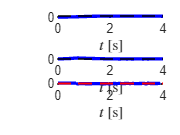

t = dt*(0:N)';
figure(1)
tiledlayout(3,1)
nexttile(1)
stairs(t,x(1,:),'b','LineWidth',2)
hold on
plot([t(1),t(end)],[data.a(1),data.a(1)],'--r')
plot([t(1),t(end)],[r,r],'--k')
grid on
xlabel("$t$ [s]",'Interpreter','latex')
ylabel("$x(t)$ [m]",'Interpreter','latex')
nexttile(2)
stairs(t,x(2,:),'b','LineWidth',2)
hold on
plot([t(1),t(end)],[0,0],'--k')
grid on
xlabel("$t$ [s]",'Interpreter','latex')
ylabel("$\dot{x}(t)$ [m/s]",'Interpreter','latex')
nexttile(3)
stairs(t(1:end-1),u,'b','LineWidth',2)
hold on
plot([t(1),t(end)],[data.a(2),data.a(2)],'--r')
plot([t(1),t(end)],-[data.a(2),data.a(2)],'--r')
grid on
xlabel("$t$ [s]",'Interpreter','latex')
ylabel("$u(t)$ [m/s$^2$]",'Interpreter','latex')

Plot of $\mathrm{Proj}_x\mathcal{O}_{\infty}^{\epsilon}$ and the state trajectory.

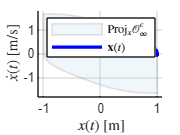

figure(2)
data.RPoinf.plot('color','lightblue','alpha',0.2,'edgealpha',0.1)
hold on
plot(x(1,1:end-1),x(2,1:end-1),'b','LineWidth',2)
legend('$\mathrm{Proj}_x\mathcal{O}_{\infty}^{\epsilon}$','$\mathbf{x}(t)$','Interpreter','Latex')
xlabel("$x(t)$ [m]",'Interpreter','latex')
ylabel("$\dot{x}(t)$ [m/s]",'Interpreter','latex')

### Solvetime performance

disp(strcat("Average solvetime [ms]: ", num2str(1000*mean(st))))

Average solvetime [ms]: 0.87741


disp(strcat("Maximum solvetime [ms]: ", num2str(1000*max(st))))

Maximum solvetime [ms]: 1.5585
